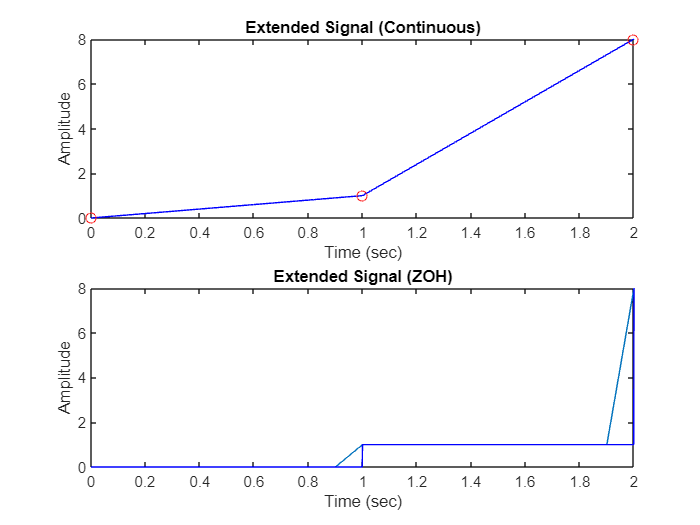

% Input signal
y = [0, 1];
time = [0, 1];

% Sampling rate
fs = 10;

% Generate ZOH signal
t_zoh = 0:1/fs:max(time);
y_zoh = interp1(time, y, t_zoh, 'previous');

% Add new values to the end of the signal
y_extended = [y, new_value];
time_extended = [0:length(y_extended)-1];

% Plot extended signal
t_cont_ext = 0:0.001:max(time_extended);
y_cont_ext = interp1(time_extended, y_extended, t_cont_ext, 'linear');

figure;
subplot(2,1,1);
plot(t_cont_ext, y_cont_ext, 'b-', time_extended, y_extended, 'ro');
title('Extended Signal (Continuous)');
xlabel('Time (sec)');
ylabel('Amplitude');

t_zoh_ext = 0:1/fs:max(time_extended);
y_zoh_ext = interp1(time_extended, y_extended, t_zoh_ext, 'previous');

subplot(2,1,2);
plot(t_zoh_ext, y_zoh_ext, t_cont_ext, interp1(t_zoh_ext, y_zoh_ext, t_cont_ext, 'previous'), 'b-');
title('Extended Signal (ZOH)');
xlabel('Time (sec)');
ylabel('Amplitude');


t = 1.5;

if t <= max(t_zoh_ext)
    y_t = interp1(t_zoh_ext, y_zoh_ext, t, 'previous');
    fprintf('Value of ZOH signal at t = %.2f seconds: %.2f\n', t, y_t);
else
    fprintf('t is out of range of ZOH signal.\n');
end

Value of ZOH signal at t = 1.50 seconds: 1.00
